clear KalmanFilterSpeechEnhancement
clc

## Setting up the variables before jumping into processing.

WinLenSec = 0.0025; % Window length in seconds.
HopPercent = 1; % percentage of hopping.
AROrder = 20; % Auto regressive filter order.
NumIter = 7;

## Reading Input signal and creating noisy input as well.

[Input, Fs] = audioread('input.wav');
Input = Input(:,1);
Noise = normrnd(0,sqrt(0.01),size(Input));
NoisyInput = Input + Noise;
Time = (0:1/Fs:(length(Input)-1)/Fs)';

## Chopping session.

WinLenSamples = fix(WinLenSec * Fs);
Window = ones(WinLenSamples,1);
[ChoppedSignal, NumSegments] = Chopper(NoisyInput, WinLenSamples, Window, HopPercent);

## Matrix initializations.

H = [zeros(1,AROrder-1),1];   % Measurement matrix.
R = var(Noise);     % Variance of noise.

[FiltCoeff, Q] = lpc(ChoppedSignal, AROrder);   % Finding filter coefficients.

P = R * eye(AROrder,AROrder);   % Error covariance matrix.
Output = zeros(1,size(NoisyInput,1));   % Allocating memory for output signal.
Output(1:AROrder) = NoisyInput(1:AROrder,1)';   % Initializing output signal according to equation (13)
OutputP = NoisyInput(1:AROrder,1);

## Iterators.

i = AROrder+1;
j = AROrder+1;

## Processing.

for k = 1:NumSegments   % For every segment of chopped signal...
    jStart = j;     % Keeping track of AROrder+1 value for every iteration.
    OutputOld = OutputP;    % Keeping the first AROrder amount of samples for every iteration.
    
    for l = 1:NumIter
        A = [zeros(AROrder-1,1) eye(AROrder-1); fliplr(-FiltCoeff(k,2:end))];
        
        for ii = i:WinLenSamples
            OutputC = A * OutputP;
            Pc = (A * P * A') + (H' * Q(k) * H);
            K = (Pc * H')/((H * Pc * H') + R);
            OutputP = OutputC + (K * (ChoppedSignal(ii,k) - (H*OutputC)));
            Output(j-AROrder+1:j) = OutputP';
            P = (eye(AROrder) - K * H) * Pc;
            j = j+1;
        end
        
        i = 1;
        if l < NumIter
            j = jStart;
            OutputP = OutputOld;
        end
        
        % update lpc on filtered signal
        [FiltCoeff(k,:), Q(k)] = lpc(Output((k-1)*WinLenSamples+1:k*WinLenSamples),AROrder);
    end
end
Output = Output';

disp(Output)

    0.0538
    0.1835
   -0.2256
    0.0841
    0.0358
   -0.1369
   -0.0459
    0.0440
    0.3483
    0.2795
   -0.1300
    0.2966
    0.0509
   -0.0069
    0.0452
   -0.0365
   -0.0026
    0.1411
    0.1673
    0.1545
    0.0589
    0.1843
   -0.0500
    0.0816
    0.0060
    0.0026
   -0.0105
    0.0200
    0.2633
    0.1548
   -0.0828
    0.2069
    0.0340
    0.0317
    0.0191
    0.0009
    0.0530
    0.0517
    0.0889
    0.1310
    0.0000
    0.0170
    0.0430
    0.0396
   -0.0483
    0.0719
   -0.0117
    0.0305
    0.0964
   -0.0440
    0.0276
   -0.0270
   -0.0259
    0.0390
   -0.1321
    0.0662
    0.0103
   -0.0408
    0.0941
   -0.0329
   -0.0165
   -0.0075
   -0.0570
    0.0178
   -0.0708
    0.0162
    0.0108
    0.0238
    0.0299
    0.0184
   -0.0315
   -0.0045
   -0.0113
   -0.0296
   -0.0166
    0.0636
   -0.0344
    0.0114
   -0.0115
    0.0573
   -0.0287
    0.0053
    0.0077
    0.0387
   -0.0025
    0.0044
   -0.0439
   -0.0177
   -0.0397
    0.0898
   -0.0163

## Plotting the results

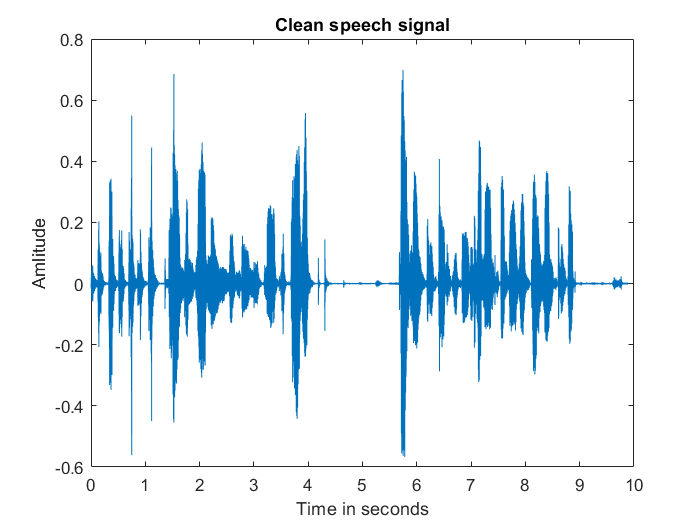

figure
plot(Time, Input)
xlabel('Time in seconds')
ylabel('Amlitude')
title('Clean speech signal')

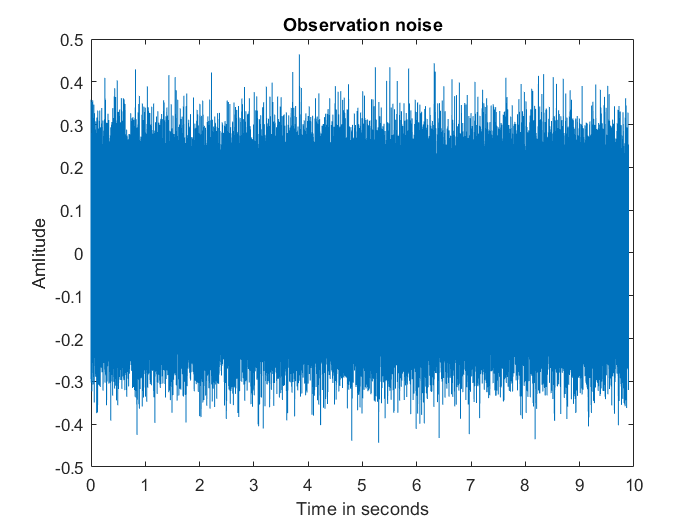

figure
plot(Time, Noise)
xlabel('Time in seconds')
ylabel('Amlitude')
title('Observation noise')

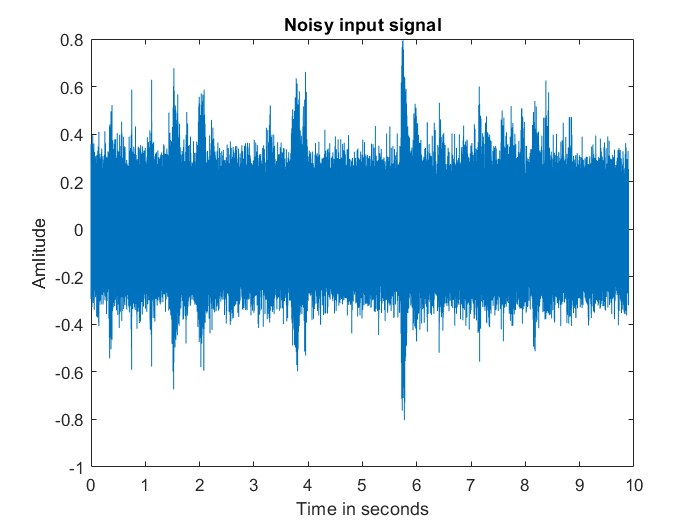

figure
plot(Time, NoisyInput)
xlabel('Time in seconds')
ylabel('Amlitude')
title('Noisy input signal')

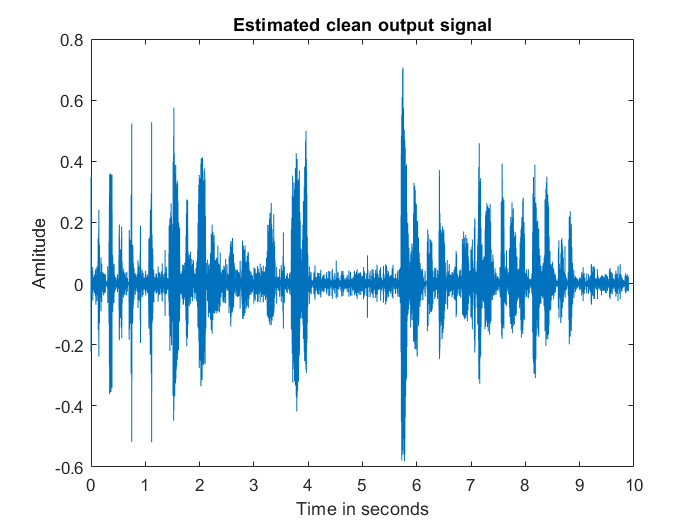

figure
plot(Time, Output)
xlabel('Time in seconds')
ylabel('Amlitude')
title('Estimated clean output signal')